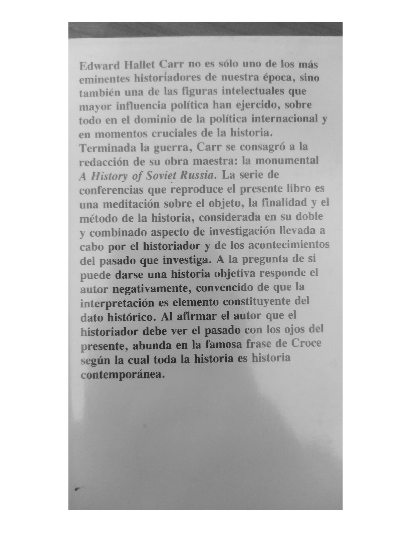

I = rgb2gray(imread("Imagen.jpeg"));
imshow(I);

g = graythresh(I)

g = 0.6314

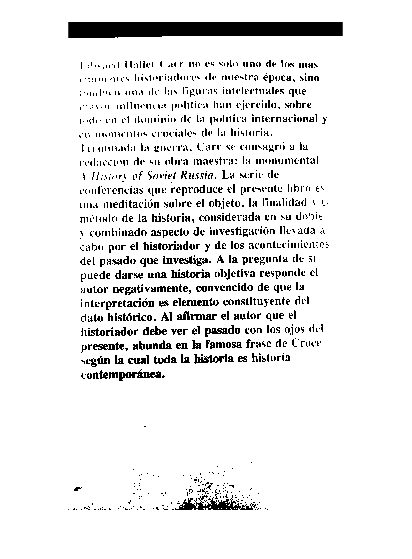

BIN = I > 135;
remove = strel('disk',50);
imshow(BIN); 

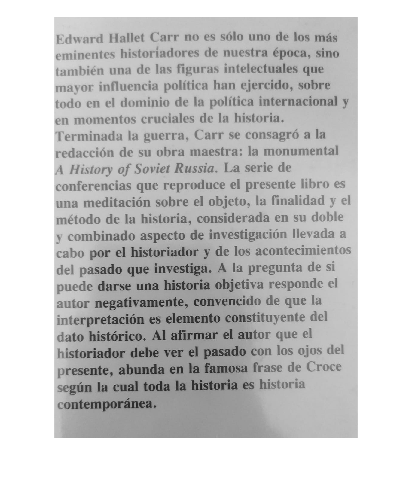

A = imcrop(I,[40 100 1010 1400]);
imshow(A);

Final_Vector = colfilt(A,[31 61],'sliding', @seek);
B = A < Final_Vector-10;
imshow(B, []);
labeledImage = bwconncomp(B)

labeledImage = struct with fields:
    Connectivity: 8
       ImageSize: [1401 1011]
      NumObjects: 940
    PixelIdxList: {1×940 cell}


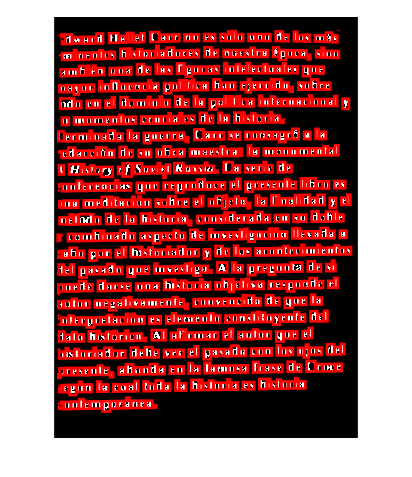

measurements = regionprops(labeledImage,'BoundingBox');
for k = 1 : length(measurements)
    thisBB = measurements(k).BoundingBox;
    rectangle('Position', [thisBB(1),thisBB(2),thisBB(3),thisBB(4)],...
    'EdgeColor','r','LineWidth',2 )
end

function [y] = seek(window_col)
    [f c] = size(window_col);
    mean = sum(window_col)/f;
    y = mean;
end
